# **EllipticCE**

Complementary complete elliptic integral of the second kind 

## Definition


$$E\textrm{'}\left(m\right)\equiv E\left(1-m\right)$$



$$\mathit{\mathbf{E}}\textrm{'}\left(k\right)\equiv E\textrm{'}\left(k^2 \right)$$


where *k *is the modulus, *m *is the parameter.

Domain: $m\ge 0$, or  $-\infty <k<\infty$. For the specified domain, the  codomain is real numbers.

Special values:

$E\left(0\right)=1,$   $E\left(1\right)=\frac{\pi }{2}$,   $E\left(\infty \right)=\infty$

## Syntax

Y = EllipticCE(K)

y = elCE(k)

Y = mEllipticCE(M)

y = melCE(m)

## Description

**Y = EllipticCE(K)** returns the value of the complemetary complete elliptic integral of the second kind $E\textrm{'}\left(k\right)$ for each element of the array  K (modulus).  K must be real array or scalar. **EllipticCE** is the wrapper function which calls the functions **elCE** element-wise via the function **ufun1**.

**y = elCE(k)** returns the value of the complementary complete elliptic integral of the second kind  $\mathit{\mathbf{E'}}\left(k\right)$ for  the modulus k. It is assumed that  k is real scalars without check. y is NaN if k is invalid or convergence failed. **elCE** is the wrapper function which calls the functions **melCE**.

**Y = mEllipticCE(M)** returns the value of  the complementary complete elliptic integral of the second kind $E\textrm{'}\left(m\right)$ for each element of the array  M (parameter).  M must be real array or scalar. **mEllipticCE** is the wrapper function which calls the functions melCE element-wise via the function **ufun1**.

**y = melCE(m)** compute value of  the complementary complete elliptic integral of the second kind $E\textrm{'}\left(m\right)$ for  the parameter m. It is assumed that  m is real scalars without check. y is NaN if m is invalid or convergence failed.  **melCE **call the Carlson's function **rf **for calculation of $\mathit{K'}\left(m\right)$ ([1-2]).

## Precision

For  ${10}^{-9} <m<{10}^6$ the relative error of **melCE **is less than ${10}^{-14}$ .

## **Numerical Examples**

**Scalar input**

format long
k = 0.5 % k >= 0

k = 0.5000

[elCE(k), EllipticCE(k), melCE(k^2), mEllipticCE(k^2)]

ans =    1.211056027568460   1.211056027568460   1.211056027568460   1.211056027568460


m = 0.5; % m >= 0 
[elCE(sqrt(m)), EllipticCE(sqrt(m)), melCE(m), mEllipticCE(m)]

ans =    1.350643881047676   1.350643881047676   1.350643881047676   1.350643881047676


Accuracy. 

fprintf('%.16g\n',elCE(2)) % Maple 18D = 2.422112055136919 05

2.422112055136919


Special values

disp(elCE(0)-1)

     0



disp(elCE(1) - pi/2)

     0



melCE(inf)

ans = Inf

elCE(-inf)

ans = Inf

Identities

k = (sqrt(3)-1)/2/sqrt(2);
disp(elCE(k) - pi*sqrt(3)/4/elCK(k) - sqrt(2/3)*k*elCK(k))

     4.440892098500626e-16



k = 200;
disp(elCE(k) - melCE(k^2))

     0



disp(elCE(k)-elE(sqrt(1-k^2)))

     0



m=200;
disp(melCE(m) - melE(1-m))

     0



k=0.5; %|k|<1
disp(elE(k)*elCK(k)+elCE(k)*elK(k)-elK(k)*elCK(k)-pi/2)

     8.881784197001252e-16



[MATLAB example](https://www.mathworks.com/help/symbolic/ellipticce.html)

format short
s = [mEllipticCE(0), mEllipticCE(pi/4), mEllipticCE(1),  mEllipticCE(pi/2)];
fprintf('%.10g %.10g %.10g %.10g\n',s)

1 1.482786927 1.570796327 1.775344699


**Vector input**

k = [-0.2, -0.1, 0.999];
disp(EllipticCE(k)-EllipticE(sqrt(1-k.^2)))

   1.0e-15 *

    0.2220         0         0



**Matrix input**

K=[1/2 1/3 1/4; -1/2 -1/3 -1/4]

K =     0.5000    0.3333    0.2500
   -0.5000   -0.3333   -0.2500


disp(EllipticE(K).*EllipticCK(K)+EllipticCE(K).*EllipticK(K)...
    -EllipticK(K).*EllipticCK(K)-pi/2*ones(size(K)))

   1.0e-15 *

    0.8882         0         0
    0.8882         0         0



## **Graphs**

**Example 1**

[MATLAB example](https://www.mathworks.com/help/symbolic/ellipticce.html)

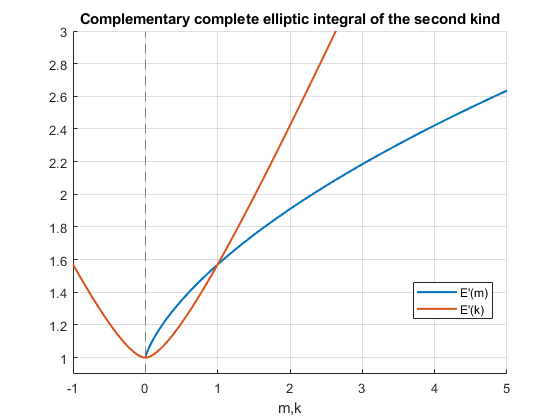

figure
hold on
fplot(@(m) mEllipticCE(m),[-1 5], 'LineWidth',1.5)
fplot(@(k)EllipticCE(k),[-1 5],'LineWidth',1.5)
title('Complementary complete elliptic integral of the second kind')
legend('E''(m)','E''(k)','Location','best')
xlabel('m,k')
ylim([0.9 3])
grid on
hold off

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Elliptic integrals, Wikipedia](https://en.wikipedia.org/wiki/Elliptic_integral)

## **References**

[1] B.C. Carlson, Computing Elliptic Integrals by Duplication. Numerische Mathematik 33, 1-16, 1979.

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also